# Hands-on project 1:  Non-NN Machine Learning

## Preparation of workspace and constants

First of all we clean the workspace in order to have a common starting point.

% Clean workspace
clear;

After that we set some NECESSARY parameters to the workflow:

-  DATASET_PATH: relative path of the used dataset

- K_FOLD_PARTITIONS: number of subdivision of the training set during cross validation of the models

- PERCENTAGE_DATA_TRAINING: percentage of data used to train the model (from 0% to 100%). Suggested values are between 75% and 80%.

- NUMBER_OPTIMIZATION: Number of iteration in Bayesian optimization of the models

% Constants used
DATASET_PATH ="data/seeds_dataset.csv";
K_FOLD_PARTITIONS = 6;
PERCENTAGE_DATA_TRAINING = 80; % From 0 to 100
NUMBER_OPTIMIZATION = 100;

## Reading data from dataset and shuffling

In order to obtain a randomized order of the data (in the original dataset we had all the data sorted by class) we use the function randperm.

After that we divide the total dataset in training set and test set.

We do this operation in order to have a confirmation that the model is not overfitted on the data we used to train it. Inserting a dataset in testing meanings that the model has never seen those data so it has to guess the prediction since it doesn't have a precise clue.

% Import dataset from file
dataset = readtable(DATASET_PATH);

% Shuffle data to obtain a random order
shuffled = dataset(randperm(size(dataset, 1)), :);


Since the optimization in matlab doesn't allow to normalize the data, we'll do it manually while we divide the test set from the train set.

division_row_data = (PERCENTAGE_DATA_TRAINING/100) * size(shuffled,1);
% normalized_data = (normalize(shuffled(:,1:7),"center","mean")); 
% normalized_data = cat(2,normalized_data,shuffled(:,8));
% Normalized data
% norm_testSet = normalized_data(1 : division_row_data,:);
% norm_trainSet = normalized_data(division_row_data + 1 : size (shuffled, 1),:);

% Raw data
trainSet = shuffled(1 : division_row_data,:);
testSet = shuffled(division_row_data + 1 : size (shuffled, 1),:);

The division in labels and data is made in order to have a more human friendly function generation (code easier to be read).

% Division of data and labels
trainLabels = trainSet(:, 8);
trainSet(:,8) = [];
testLabels = testSet(:, 8);
testSet(:,8) = [];

% norm_trainLabels = trainLabels;
% norm_trainSet(:,8) = [];
% norm_testLabels = norm_testSet(:, 8);
% norm_testSet(:,8) = [];

% Cleaning of data
clear percentage_data_train division_row_data shuffled; %normalized_data;

## Model creation and cross validation

### Model creation

After have used the application "Classification Learners" I find out the most suitable models to achieve the classification of the wheat. Since NN weren't allowed in this task, the most promising models found were Linear SVM and Cubic KNN.

### SVM

Most primising parameters for SVM, after an hyperparameters optimization, were a linear function and standardized data. Here explained what this means:

-     Linear: the prediction is based on a dividion of the data given by a linear function

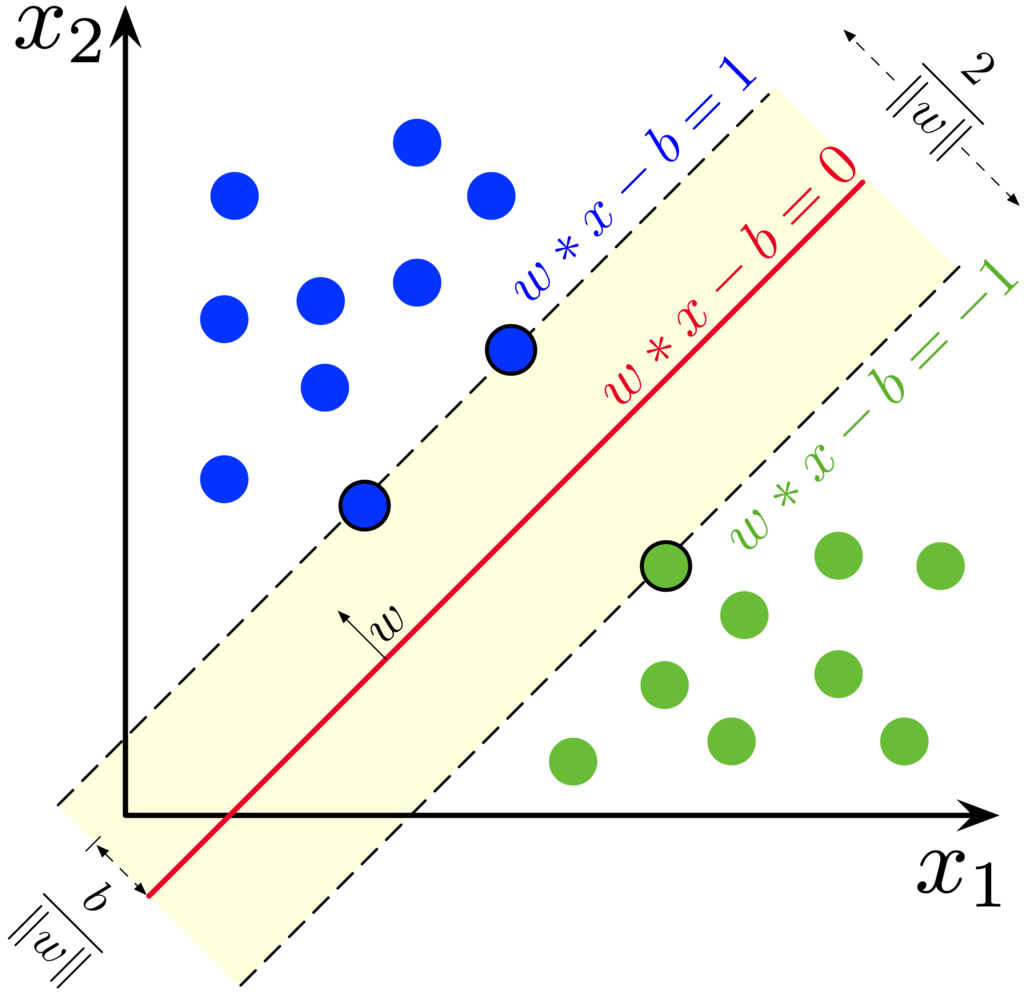

- Standardize: according to Matlab help guide, this option centers and scales each predictor variable by the corresponding weighted column mean and standard deviation

% SVM
template = templateSVM(...
    'KernelFunction', 'linear', ...
    'Standardize', true);

After the definition of the SVM, we fit the model using the function "fitecoc" that allows us to create a non-binary classifier. To create the model we use the train dataset and labels.

 SVM = fitcecoc(...
    trainSet, ...
    trainLabels, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', {'canadian'; 'kama'; 'rosa'});

### KNN

As said before, also for KNN model the best parameters were cubic distance with 10 neighbors. 

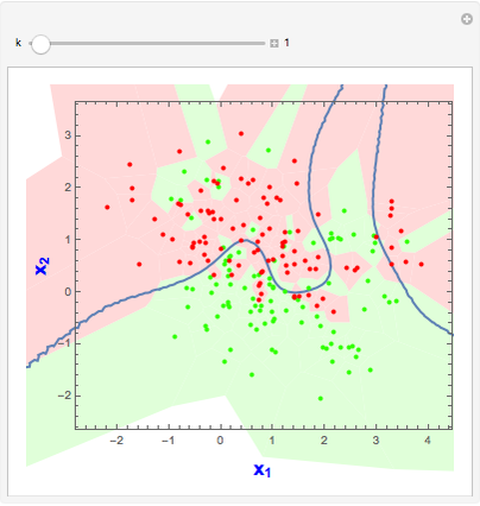

This options means:

- Distance: function that is used to calculate the distance between the data and the neighbors

- Exponent: exponent of the polynomial function

- DistanceWeight: Way the different neighbors are weighted

- Standardize: according to Matlab help guide, this option centers and scales each predictor variable by the corresponding weighted column mean and standard deviation

 % KNN
 KNN = fitcknn(trainSet, trainLabels,'Distance', 'Minkowski', ...
        'Exponent', 3, ...
        'NumNeighbors', 10, ...
        'DistanceWeight', 'Equal', ...
        'Standardize', true);

### Cross validation

After the setup of the models we procede to obtain a cross validation of the data.

Cross validation of data is usefull since it helps us to have an augmentation of the dataset that we use to train the models. This is because we divide the entire train set in N sub-sets and then we try to validate the models for each of them.

The picture above shows the process.

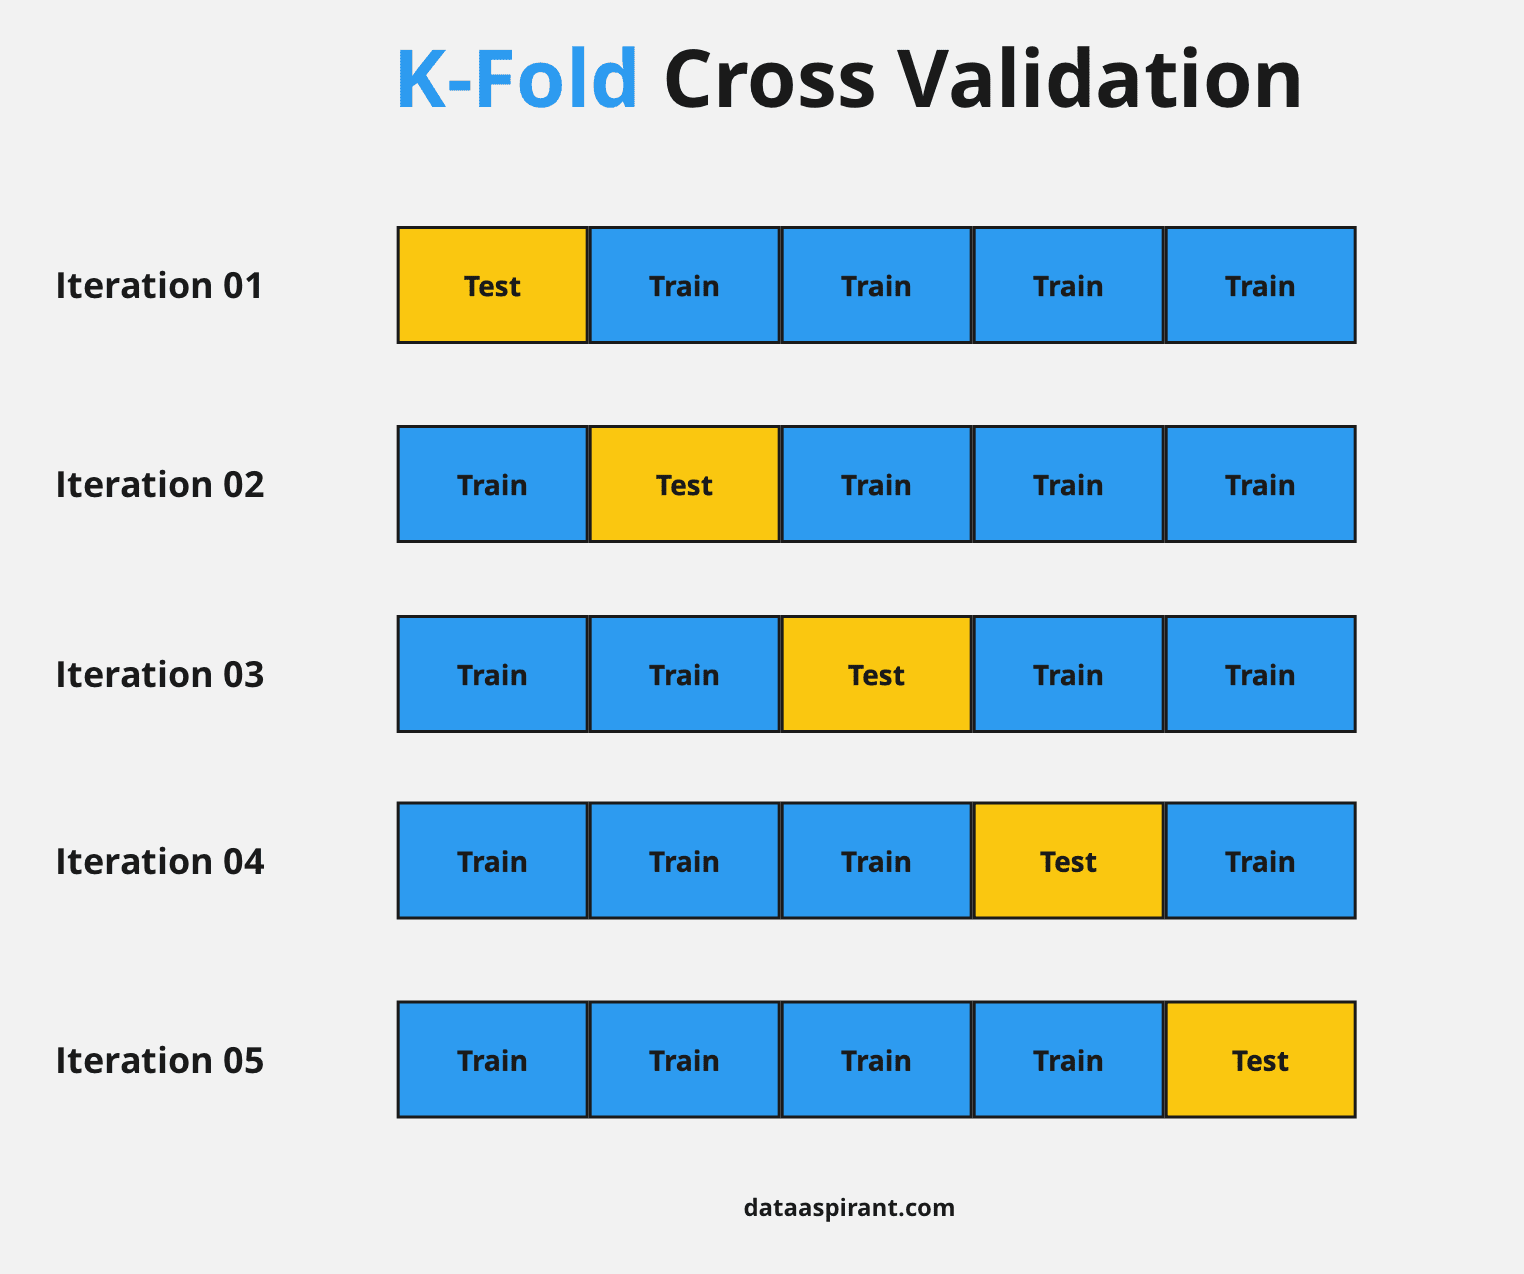

If the dataset has problems or the model is not balanced, then cross validation helps us to find these problems.

% Perform cross-validation
CVModel_SVM = crossval(SVM, 'KFold', K_FOLD_PARTITIONS);
CVModel_KNN = crossval(KNN, 'KFold', K_FOLD_PARTITIONS);

% Calculattion of validation accuracy
validationAccuracySVM = 1 - kfoldLoss(CVModel_SVM, 'LossFun', 'ClassifError');
validationAccuracyKNN = 1 - kfoldLoss(CVModel_KNN, 'LossFun', 'ClassifError');
accuracy = kfoldLoss(CVModel_SVM, 'Mode', 'individual');

Here the accuracy values obtained from SVM and KNN cross validation:

disp("Accuracy of cross validation folders in SVM: ");

Accuracy of cross validation folders in SVM: 


for i = 1 : size(accuracy)
    disp(100 - accuracy(i)*100 + "%");
end

96.4286%
96.4286%
92.8571%
92.8571%
96.4286%
85.7143%


disp("Mean accuracy in validation for SVM: " + validationAccuracySVM*100 + "%");

Mean accuracy in validation for SVM: 93.4524%


accuracy = kfoldLoss(CVModel_KNN, 'Mode', 'individual');
disp("Accuracy of cross validation folders in KNN: ");

Accuracy of cross validation folders in KNN: 


for i = 1 : size(accuracy)
    disp(100 - accuracy(i)*100 + "%");
end

92.8571%
85.7143%
96.4286%
96.4286%
82.1429%
96.4286%


disp("Mean accuracy in validation for KNN: " + validationAccuracyKNN*100 + "%");

Mean accuracy in validation for KNN: 91.6667%


% Cleaning of data
clear CVModel_SVM CVModel_KNN validationAccuracySVM validationAccuracyKNN accuracy;

## Optimized models and Comparison

### Optimization

Before testing our models, we try to optimize them using Bayesan optimization:

% SVM optimized model
opt_template = templateSVM("Standardize", true);
Opt_SVM = fitcecoc(trainSet, trainLabels, ...
    'OptimizeHyperparameters', {'BoxConstraint','KernelScale','KernelFunction','PolynomialOrder'} ,...
    'HyperparameterOptimizationOptions', struct('CVPartition',cvpartition(table2cell(trainLabels),'KFold',K_FOLD_PARTITIONS), ...
    'AcquisitionFunctionName','expected-improvement-plus', ...
    'MaxObjectiveEvaluations', NUMBER_OPTIMIZATION), "Learners", opt_template);

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint| 

% KNN optimized model
opt_template = templateKNN("Standardize", true);
Opt_KNN = fitcecoc(trainSet, trainLabels,'OptimizeHyperparameters',{'NumNeighbors','Distance','DistanceWeight'},...
    'HyperparameterOptimizationOptions', struct('CVPartition',cvpartition(table2cell(trainLabels),'Kfold',K_FOLD_PARTITIONS), ...
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'MaxObjectiveEvaluations', NUMBER_OPTIMIZATION),"Learners", opt_template);

Now that we have verified and optimized the models we can proced to obtain a real prediction based on our test set.

So now we create a prediction (SVM_prediction and KNN_prediction) and we compare them with the testLabel saved at the beginning.

On way to show how good is our prediction is to use a Confusion chart. On it can be seen which errors have been made during the prediction.

### SVM confusion chart

% Test SVM
SVM_prediction = SVM.predict(testSet);
svm_confusion_chart = confusionchart(table2array(testLabels), SVM_prediction, Title="SVM Confusion Chart");     % plot confusion chart
% Test Optimized SVM
Optimized_SVM_prediction = Opt_SVM.predict(testSet);
opt_svm_confusion_chart = confusionchart(table2array(testLabels), Optimized_SVM_prediction, Title=" Optimized SVM Confusion Chart");     % plot confusion chart
% Calculation accuracy SVM
    errors = strcmp(SVM_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for SVM: " + accuracy + "%");

% Cleaning of data
clear errors accuracy;

% Calculation accuracy Optimized SVM
    errors = strcmp(Optimized_SVM_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for optimized SVM: " + accuracy + "%");

% Cleaning of data
clear errors accuracy;

### KNN confusion chart

% Test KNN
KNN_prediction = KNN.predict(testSet);
knn_confusion_chart = confusionchart(table2array(testLabels), KNN_prediction, Title="KNN Confusion Chart");     %plot confusion chart
% Test Optimized KNN
Optimized_KNN_prediction = Opt_KNN.predict(testSet);
opt_knn_confusion_chart = confusionchart(table2array(testLabels), Optimized_KNN_prediction, Title="Optimized KNN Confusion Chart");     %plot confusion chart
% Calculation accuracy KNN
    errors = strcmp(KNN_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for KNN: " + accuracy + "%");
% Cleaning of data
clear errors accuracy;

% Calculation accuracy Optimized KNN
    errors = strcmp(Optimized_KNN_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for optimized KNN: " + accuracy + "%");
% Cleaning of data
clear errors accuracy PERCENTAGE_DATA_TRAINING DATASET_PATH K_FOLD_PARTITIONS;